# Aerial Robotics

## Week 2

We hope you are having a good time and learning a lot already! 

This week, we will first focus on the kinematics of quadrotors. Then, you will learn how to derive the dynamic equations of motion for quadrotors. To build a better understanding of these notions, some essential mathematical tools are discussed and learned about the 2D controller design of quadcopters. 

**So to recap what we have learnt so far:**

- A quadcopter has 4 (2 $CW$ and 2 $CCW$) rotating propellers

- Each Propeller creates $F =K_f * \omega ²$ force in a direction perpendicular to its plane and Moment $M = K_m * \omega ²$ around its perpendicular axis.

- A drone can be in any x, y, z position and theta $(\theta )$, phi $(\varphi )$ and psi $(\Psi )$ orientation.

- When a drone wants to move in the z-direction it needs to generate appropriate force (total thrust divided by 4) on each propeller. When it wants to move in either x or y direction, it makes respecting $\theta $/$\varphi $ angle along with generating required force

- 1D controller Design

## Dynamical Systems

First, to kick start this week we will first understand what dynamical systems are?

Dynamical systems are mathematical objects used to model physical phenomena whose state (or instantaneous description) changes over time. These models are used in financial and economic forecasting, environmental modelling, medical diagnosis, industrial equipment diagnosis, and a host of other applications.

But we are focused on quadcopters, right? 

Let me ask you a simple question: how many state parameters are required to describe the motion of a quadrotor in 3D?... Think of it!

 To understand more and maybe you’ll get an answer at the end.

[Dynamical Systems](https://youtu.be/CMKp6OWk78w)

There is an example below illustrating the 2 dof system example shown in the video(very close to it to be fair), it is not an 'exercise' as you still need some idea on control to understand what exactly is happening (which you will gain in this week) but is a very neat way to look at it, this example has been taken from the following website and is just to give you the 'feel' of controls so do have a look at it...: [Link](https://ctms.engin.umich.edu/CTMS/index.php?example=InvertedPendulum&section=ControlPID)

M = 0.5;
m = 0.2;
b = 0.1;
I = 0.006;
g = 9.8;
l = 0.3;
q = (M+m)*(I+m*l^2)-(m*l)^2;
s = tf('s');

'tf' requires one of the following:
  Control System Toolbox
  DSP System Toolbox
  Model Predictive Control Toolbox
  RF Toolbox
  Signal Processing Toolbox

P_pend = (m*l*s/q)/(s^3 + (b*(I + m*l^2))*s^2/q - ((M + m)*m*g*l)*s/q - b*m*g*l/q);%Equation of motion
Kp = 100;
Ki = 1;
Kd = 20;%you're encouraged to twirk these values and see how the response changes...
C = pid(Kp,Ki,Kd); %Note you won't know these functions as of yet just ignore and understand the results
T = feedback(P_pend,C);
t=0:0.01:10;
impulse(T,t)
title({'Response of Pendulum Position to an Impulse Disturbance'});

Hopefully by tweaking the example you might have got the idea that it is pretty similar to 1dof controller which we had made...

## Quadrotor Dynamics

To understand quadrotor dynamics i.e equation of motion, moments and to formulate its dynamics we will first need to understand quadrotor kinematics and it requires some mathematical background 

When tracking drone’s motion, we need to handle data in Earth/Inertial and Body Frames

[Transformation](https://youtu.be/Xeemdai9e9Y)

To measure above stated theta, phi and psi angles, usually drone’s onboard IMU sensor is used. This sensor measures how fast the drone's body is rotating around its body frame and provides that angular velocity as its output. When processing these IMU outputs, we need to be careful and understand that angular velocities sent by it are not with respect to the earth frame, but are with respect to its Body Frame. 

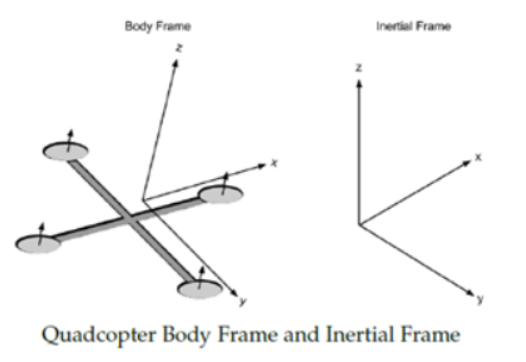

Above diagram shows both these frames for reference.

To convert angular data from Body Frame to Inertial Frame, a Rotational Matrix is used

Before we dive  into rotational matrices, I really would encourage you to have a look at the following [video](https://youtu.be/kYB8IZa5AuE) to get a much better intuition on what we are doing (though our's is a very specific case of it but still helps in clearing a lot of concepts...), in fact after you have gone through it below is a small example of what you have seen in that video do tinker with it as it will later help you when it comes to 3D transformations...

%Type in the transforming matrix below: (One is already given)
clf
set(gcf,'Visible','on');
grid on;
M = [1/sqrt(2) -1/sqrt(2);1/sqrt(2) 1/sqrt(2)] % a note here just don't keep offdiagonal entrie's 0,0 or else you'll get an animation that squishes the plot and returns it backs
title({''});
xlabel('');
ylabel('');
T = [1 0;0 1]; %initialization
for t = 0:200
    T(1,1) = ((200-t)*(1-M(1,1))/200)+M(1,1);
    T(2,1) = ((200-t)*(-M(2,1))/200)+M(2,1);
    T(1,2) = ((200-t)*(-M(1,2))/200)+M(1,2);
    T(2,2) = ((200-t)*(1-M(2,2))/200)+M(2,2);
    init1 = T*[-5;100];
    init2 = T*[-5;-100];
    hold on
    plot([init1(1),init2(1)],[init1(2),init2(2)]);   
    quiver(0,0,T(1,2),T(2,2),1,'r','linewidth',2);
    quiver(0,0,T(1,1),T(2,1),1,'r','linewidth',2);
    for i = -4:5
         xlim([-5,5]);
    ylim([-5,5]);
        plot([(T(1,1)*i+100*T(1,2)),(T(1,1)*i-100*T(1,2))],[(T(2,1)*i+100*T(2,2)),(T(2,1)*i-100*T(2,2))]);
    end
    for i = -4:5
         xlim([-5,5]);
    ylim([-5,5]);
        plot([(T(1,1)*100+i*T(1,2)),(-T(1,1)*100+i*T(1,2))],[(T(2,1)*100+i*T(2,2)),(-T(2,1)*100+i*T(2,2))]);
    end
    xlim([-5,5]);
    ylim([-5,5]);
    
    
    pause(.1);
    clf
end
hold on
for i = -4:5
    plot([(M(1,1)*i+100*M(1,2)),(M(1,1)*i-100*M(1,2))],[(M(2,1)*i+100*M(2,2)),(M(2,1)*i-100*M(2,2))]);
end
for i = -4:5
    plot([(M(1,1)*100+i*M(1,2)),(-M(1,1)*100+i*M(1,2))],[(M(2,1)*100+i*M(2,2)),(-M(2,1)*100+i*M(2,2))]);
end
hold off
xlim([-5,5]);
ylim([-5,5]);

Hope this gave you some insight if you want to experiment more visit this [link](https://www.desmos.com/calculator/upooihuy4s)

Finally hope this clears 2D rotation for you now let's shift to 3D rotations...

[Rotation](https://www.youtube.com/watch?v=WhEf0lvGCIM)

Euler showed that three coordinates are necessary to describe a general rotation, and these coordinates are called the Euler angles. 

[Euler Angle](https://www.youtube.com/watch?v=3Zjf95Jw2UE)

To understand Euler angle notation a bit better we'll again try to replicate what we did in 2D rotations, l'll give you an example of ZXY rotation, I was about to code an animation similar to above for this, but it looks like someone already had done it and kept it on internet hence am attaching the [link](https://in.mathworks.com/matlabcentral/fileexchange/23964-animeuler) here, download it and open animEuler and read the comments carefully to operate it, feel free to play with it!

We've seen two different approaches to rotations. We call the number fo unknowns in these rotations 'coordinates'. So for example, using rotation matrices, you can represent rotations with a set of nine numbers or nine coordinates, but six of those' coordinates' are redundant. So in reality we can find an arbitary 3 coordinates to do the job (The euler angles). We've done the same thing with Euler angles where you get a set of three numbers or three coordinates.

We're now going to look at a different way of looking at rotations. This involves explicitly representing the axis of rotation and the angle of rotation.

[Axis/Angle Representation](https://www.youtube.com/watch?v=zrDCI89bSp4)

Now that we've gotten familiar with this concept of rotations and displacements more generally, it's time to start thinking about the rate of change of rotations and that leads us to the concept of an angular velocity vector.

What does it mean to differentiate a rotation and get a velocity?

[Video](https://www.youtube.com/watch?v=HBLZuV92qGw)

All of you must be like AAAAhhhh too much theory…….

A numerical [example](https://www.youtube.com/watch?v=4XcoUhpdUjw) involving rigid body displacements

Also if you notice, there were a lot of equations in all the example video, matlab here comes in handy if you quickly wanna verify a few results...

syms theta
R = [cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0; 0 0 1]
diff(R)
R.'
simplify(R.'*diff(R))

You know that functions have two important properties, i.e. one to one and onto.

[Example](https://www.youtube.com/watch?v=ks6B8RuHarw)

Now that we have looked at positions and velocities (Kinematics) , it's time to study the dynamics of a quadrotor.

Basic Mathematics and prerequisite before we proceed further

- [Formulation](https://www.youtube.com/watch?v=kVRYanVeWq0)

- [Newton euler Equation](https://www.youtube.com/watch?v=poiTKrgaHqQ)

- [Principal axes and moment of inertia](https://www.youtube.com/watch?v=WPM46QeOD1g)

Now to track drone’s movements, we keep track of its state vector $X$ and its derivative $X_dot$

As our drone has 6 degrees of freedom, we usually track it by monitoring these six parameters along with their derivatives (how they are changing with time) to get an accurate estimate of the drone's position and velocity of movement. 

We do this by maintaining what is often called a state vector 

$X$** = **$[x, y, z, \varphi , \theta , \psi , \dot{x}, \dot{y}, \dot{z}, p, q, r]$ 

and its derivative $\dot{X}$**= **$[\dot{x}, \dot{y}, \dot{z}, \dot{\theta}, \dot{\varphi}, \dot\psi, \ddot{x}, \ddot{y}, \ddot{z},  \dot{p}, \dot{q}, \dot{r}]$

where *x, y and z* are positions of the drone in the Inertial frame, $\dot{x}$*, *$\dot{y}$*, and *$\dot{z}$ are positional / linear velocities in the inertial frame. 

$\varphi $, $\theta $, $\psi $ represent drone attitude / orientation in the Inertial frame whereas $\dot\varphi, \dot\theta, \dot\phi$ represent rate of change of these (Euler) angles. 

p, q, r are angular velocities in the body frame whereas $\dot{p}, \dot{q}, \dot{r}$ are its derivatives aka angular acceleration in the body frame. 

$\ddot{x}, \ddot{y}, \ddot{z}$ represents linear accelerations in the inertial Frame.

[Equation of motion](https://www.youtube.com/watch?v=R1HPPyolmNw)

Till Now, we saw the dynamical equations with a quadrotor written as matrix equations, which we call state-space form. Now, we'll see how to transform the ordinary differential equations representing a dynamical system into state-space form.

[State space](https://www.youtube.com/watch?v=Ia0lgq44azI)

If you have difficulty with digesting the state space formulation have a look at the example we had given you (and the assignment) in week 0 for solving higher order ode, that very clearly explains how powerful state space formulations are.

So you have developed planar and three-dimensional dynamic models of the quadrotor, now you will learn more about how to develop linear controllers for these models. 

Now that we understand how to write the equations of motion for a quadrotor, let's turn our attention to the model for a planar quadrotor. 

[2D QuadCopter Controller](https://youtu.be/uPsenrdsu28)

I'll again add a quick example of how a 2D controller looks with just P added to it, also I have chosen a path such that ydes_ddot and zdes_ddot don't come into picture and again no thresholds for thrust(So if they do you'll need to code that), have a look at it, tinker around, you'll obviously never attain the desired goal  with the present controller, but it is encouraged to try and convert it into a PD controller as that's what we'll ask you to do in the assignment...(also the drill's same click on the [link](https://drive.google.com/drive/folders/1iZgvUDwCSf6xB6lzU3mUTL9N7nzTMO_n?usp=sharing), download everything, open controller.m, have a look at the equations then run runsim have a look at the results in it etc.)

So this week we have understood two important concepts, Dynamics of Quadrotor and 2-D QuadCopter Controller. 

## Assignment

You will need to complete the implementation of a PD controller in the file **controller.m** so that the simulated quadrotor can follow **traj_diamond.m** trajectory. Before implementing your own functions, you should first try running runsim.m in your MATLAB environment. If you see a quadrotor falling from position (0,0), then the simulator works on your computer and you may continue with other tasks. Again, the quadrotor falls because the default outputs of the controller.m function are all zeros, and no thrust is applied. To test different trajectories, you need to modify the variable trajhandle inside runsim.m to point to the appropriate function. Examples are provided inside the runsim.m file.

For assignment submission google form link will be updaed.

Happy Learning! :)